# Team doubleE - Task 1 Report

**Team Members: Andrew Wunderlich, Jay Desai, Miles Leonard-Albert **

***CSCE585 - Machine Learning Systems***

***Fall 2020 Adversarial ML Project***

This report provides insight and analysis into Task 1, in which we create adversarial examples using the Athena framework and test the adversarial examples against several defenses to compare performance.

clear variables %reset workspace
close all; %close plots from previous runs

## Set Project Directory

projectdir = 'C:\Users\andre\CSCE585_local\project-athena'

projectdir = 'C:\Users\andre\CSCE585_local\project-athena'

## Import Project Data and Analyze Composition

All data from the Task 1 assignment was dumped into a single file [\data\predictionData.mat] which contains the following variables:

- labels: an array of the correct values associated with each training example

- predictionData: a 3-dimensional array of predicted digits, in which each row (1st dim) corresponds to an image in the test set, each column (2nd dim) corresponds to a tested attack, each layer (3rd dim) corresponds to tested defense.

### Load labels and raw prediction data

load([projectdir,'\data\predictionData.mat'])

num_images = size(predictions,1);   % rows
num_attacks = size(predictions,2);  % columns
num_defenses = size(predictions,3); % layers

if(length(labels) ~= num_images) 
    error('Number of labels not equal to number of images. Please check dimensions.')
end

### Analyze Composition by Labels

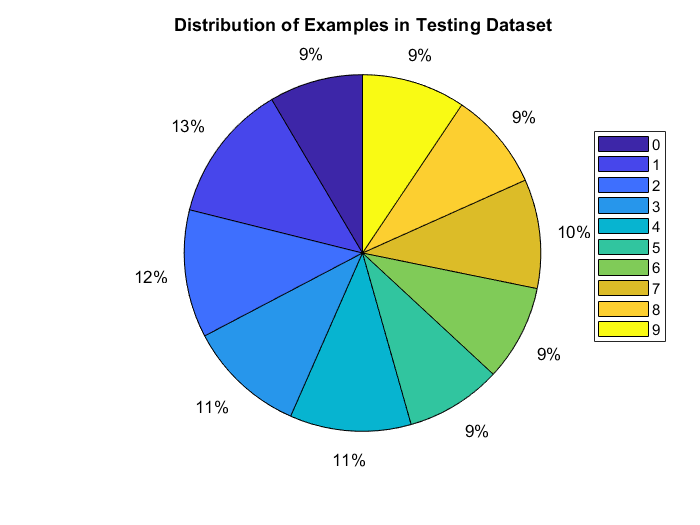

digits = unique(labels);
digitCounts = zeros(size(digits));
for i = 1:length(labels)
    for j = 1:length(digits)
        if(labels(i) == digits(j))
            digitCounts(j) = digitCounts(j) + 1;
            break;
        end
    end
end
pie(digitCounts);  title('Distribution of Examples in Testing Dataset');
legend(string(digits), 'Position', [0.85 0.45 0.1 0.2]);

## Details About Attacks

This task includes 15 attacks, featuring 3 attack types, each at 5 different intensities.  Below we plot a few examples of images from the MNIST dataset modified using the following attacks:

Spatial transformation, w/ max roation:

- 10 degrees

- 20 degrees

- 30 degrees

- 40 degrees

- 50 degrees

The spatial transormation attack can shift and rotate the image.  In this case, the attack was configured to use minimal shift but to induce significant rotation:

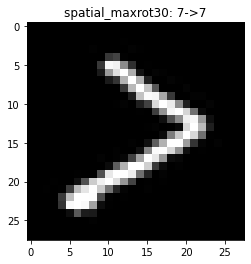

PGD, with epsilon:

- 0.03

- 0.07

- 0.10

- 0.20

- 0.30

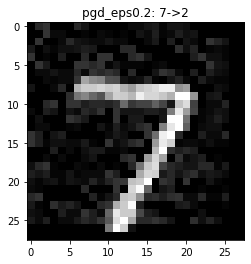

JSMA, with theta:

- 0.03

- 0.07

- 0.10

- 0.20

- 0.30

**Add photo of JSMA attack when bug is fixed**

## Analyze Error Rate

This work uses the following defense models:

- UM: The undefended model (a single CNN with no special defenses)

- MV: "Vanilla Athena" with the Majority Voting ensemble strategy

- AVEP: "Vanilla Athena" with the Average Probability ensemble strategy

- PGD-ADT: PGD Adversarial Training, a state-of-the-art Adversarial Defense

For each defense, we ran all 15,000 perturbed images (15 attacks * 1,000 of the 10,000 test images in MNIST) and obtained predictions for each.  We stored the 1,000 correct values alongside the 15,000 predicted values for each adversarial example in a single datatable, from which we can calculate error rates and plot relevant variables.

### Calculate Error Rate

errortable = -ones(size(predictions));
all_err_rates = -ones(num_attacks, num_defenses);

for i = 1:num_attacks
    for j = 1:num_defenses
        
        %To be error, the prediction must not match the label, and the
        %label must have been correctly identified but the undefended model
        %before the attack
        errortable(:,i,j) = ((predictions(:,i,j) ~= labels') & (labels' == pred_bs_um')); 
        
        %The error rate is simply the average of error values across the row
        all_err_rates(i,j) = mean(errortable(:,i,j));
    end
end

### Plot Error Rate by Attack for Each Defense

attacks = {'JSMA 0.03' 'JSMA 0.07' 'JSMA 0.10' 'JSMA 0.20' 'JSMA 0.30'...
            'PGD 0.03' 'PGD 0.07' 'PGD 0.10' 'PGD 0.20' 'PGD 0.30'...
            'SpaXfm 10' 'SpaXfm 20' 'SpaXfm 30' 'SpaXfm 40' 'SpaXfm 50'};        

#### For Undefended Model:

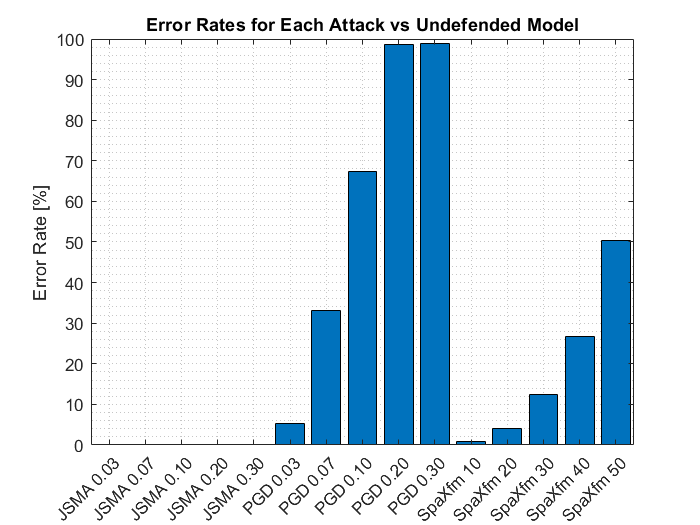

bar(categorical(attacks), all_err_rates(:,1)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs Undefended Model');

#### For AVEP Ensemble Defense:

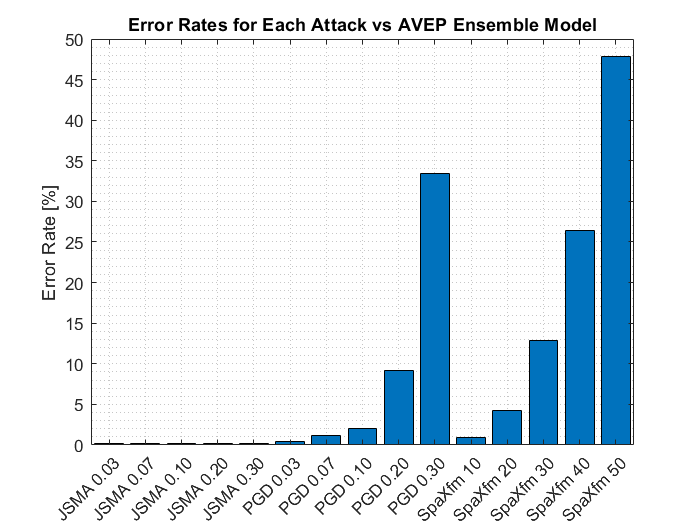

bar(categorical(attacks), all_err_rates(:,2)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs AVEP Ensemble Model');

#### For MV Ensemble Defense:

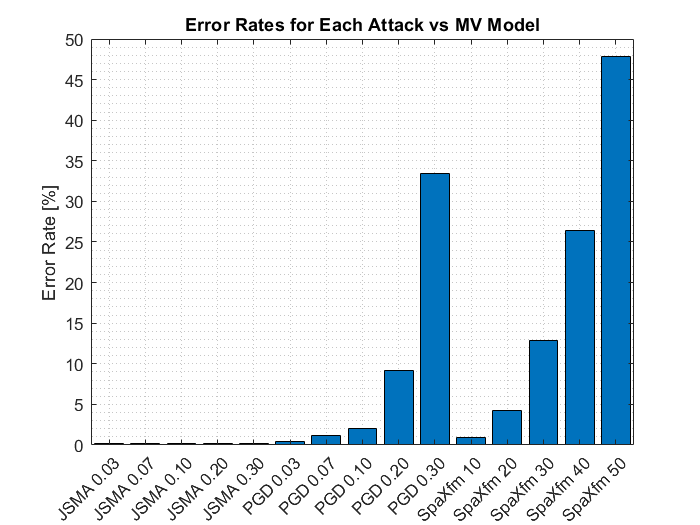

bar(categorical(attacks), all_err_rates(:,3)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs MV Model');

#### For PGD-ADT Defense:

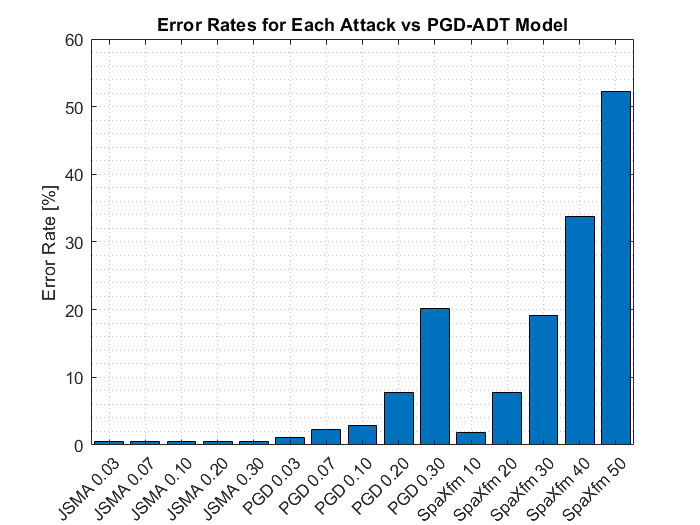

bar(categorical(attacks), all_err_rates(:,4)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs PGD-ADT Model');

### Plot Error Rate by Defense for Each Attack

defenses = {'Undefended' 'AVEP' 'MV' 'PGD-ADT'};

#### For JSMA attack:

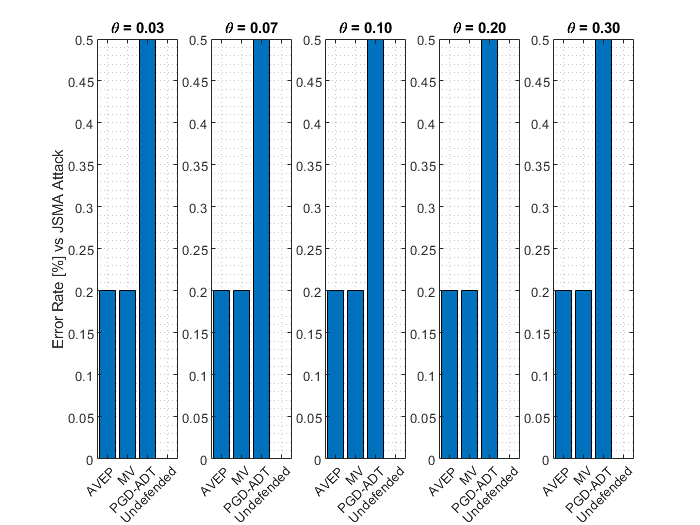

figure; title('JSMA Attack');
s1 = subplot(1,5,1);
bar(categorical(defenses), all_err_rates(1,:)*100); ylabel('Error Rate [%] vs JSMA Attack');  
title('\theta = 0.03');
s2 = subplot(1,5,2);
bar(categorical(defenses), all_err_rates(2,:)*100); 
title('\theta = 0.07');
s3 = subplot(1,5,3);
bar(categorical(defenses), all_err_rates(3,:)*100);
title('\theta = 0.10');
s4 = subplot(1,5,4);
bar(categorical(defenses), all_err_rates(4,:)*100);
title('\theta = 0.20');
s5 = subplot(1,5,5);
bar(categorical(defenses), all_err_rates(5,:)*100);
title('\theta = 0.30');
linkaxes([s1, s2, s3, s4 ,s5],'y'); %force identical y-scaling on each subplot

#### For PGD attack:

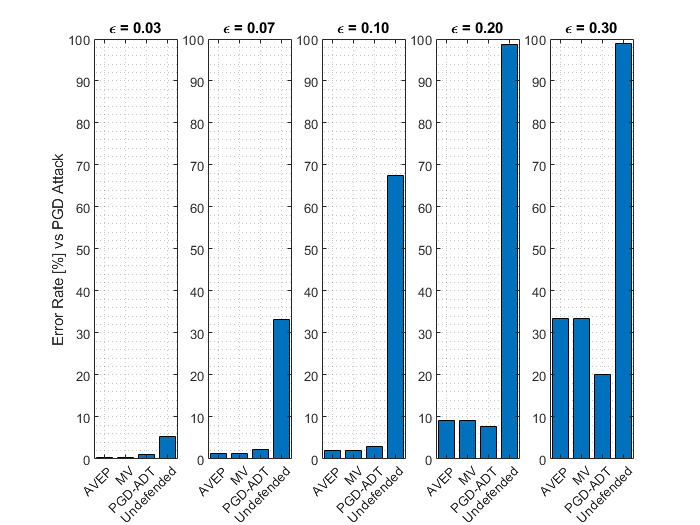

figure; 
s1 = subplot(1,5,1);
bar(categorical(defenses), all_err_rates(6,:)*100); ylabel('Error Rate [%] vs PGD Attack');  
title('\epsilon = 0.03');
s2 = subplot(1,5,2);
bar(categorical(defenses), all_err_rates(7,:)*100); 
title('\epsilon = 0.07');
s3 = subplot(1,5,3);
bar(categorical(defenses), all_err_rates(8,:)*100); 
title('\epsilon = 0.10');
s4 = subplot(1,5,4);
bar(categorical(defenses), all_err_rates(9,:)*100);
title('\epsilon = 0.20');
s5 = subplot(1,5,5);
bar(categorical(defenses), all_err_rates(10,:)*100);   
title('\epsilon = 0.30');
linkaxes([s1, s2, s3, s4 ,s5],'y'); %force identical y-scaling on each subplot

Unsurprisingly, the defended models outperform the undefended model at all attack strengths.  The difference is most pronounced around the range $0\ldotp 1<\epsilon <0\ldotp 2$, where the undefended model misclassifies more than two thirds of the attacked images, but the defended models all still classify them with >90% accuracy.

The PGD-ADT strong defense outperforms the ensemble methods at higher attack strengths in this case, but this is partially due to a very small number of weak defenses beeing used in the ensemble methods.  If more weak defenses are added, we expect that the ensemble methods would perform much better.  

#### Spatial Transformation attack:

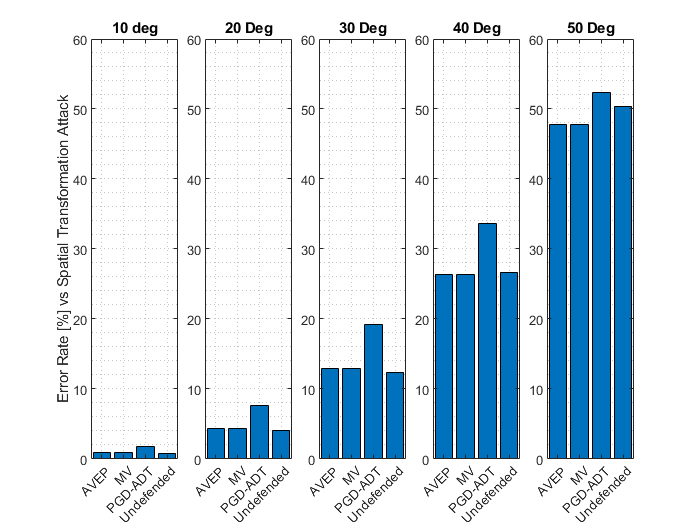

figure; 
s1 = subplot(1,5,1);
bar(categorical(defenses), all_err_rates(11,:)*100); ylabel('Error Rate [%] vs Spatial Transformation Attack');  
title('10 deg');
s2 = subplot(1,5,2);
bar(categorical(defenses), all_err_rates(12,:)*100); 
title('20 Deg');
s3 = subplot(1,5,3);
bar(categorical(defenses), all_err_rates(13,:)*100); 
title('30 Deg');
s4 = subplot(1,5,4);
bar(categorical(defenses), all_err_rates(14,:)*100);   
title('40 Deg');
s5 = subplot(1,5,5);
bar(categorical(defenses), all_err_rates(15,:)*100);   
title('50 Deg');
linkaxes([s1, s2, s3, s4 ,s5],'y'); %force identical y-scaling on each subplot

Interestingly, the defenses do very little to protect against spatial transformation attacks, with the undefended model frequently performing as well or better than the defended models. However, for low values of rotation (<20 degrees), both the defended and undefended models perform well.  This is expected due to the spatial invariance properties of convolutional neural networks.  With higher values of rotation, the models perform worse, with each model misclassifying about half of the test examples for 50 degree rotation.  

We note here that it is impossible for a classifier of this type to perform well for arbitrarily high values of rotation, considering that the picture orientation is one of the ways that the digit is properly discerned.  Indeed, a rotated '6' is indistinguishable from a '9', even for human beings.  We should also note that rotation by more than 30 degrees is visibly apparent, so rotational attacks of that strength would be clearly evident, not subtle. 